# **Quantum teleportation:**

it is a process in quantum mechanics that allows the transmission of quantum information from one location to another without physically transferring the quantum system itself. This is achieved by exploiting entanglement between two qubits and classical communication.

**The process involves the following steps:**

- **Entanglement:** A pair of qubits (Alice's and Bob's) are entangled. This means their quantum states are correlated, regardless of their physical distance.

- **Teleportation:** The qubit to be teleported (Alice's qubit) is entangled with one of the entangled qubits (Alice's).

- **Measurement:** Alice measures her two qubits. The measurement outcome determines the correction that Bob needs to apply to his qubit.

- **Correction:** Alice sends the measurement results to Bob via a classical communication channel. Bob applies the necessary correction gates to his qubit to recover the teleported state.

**Key points:**

- **No physical transfer:** Quantum teleportation does not involve physically transferring the quantum state.

- **Entanglement:** Entanglement is essential for teleportation.

- **Classical communication:** Classical communication is required to transmit the measurement results.

- **No cloning:** The no-cloning theorem prevents direct copying of a quantum state, making teleportation necessary for transmitting quantum information.

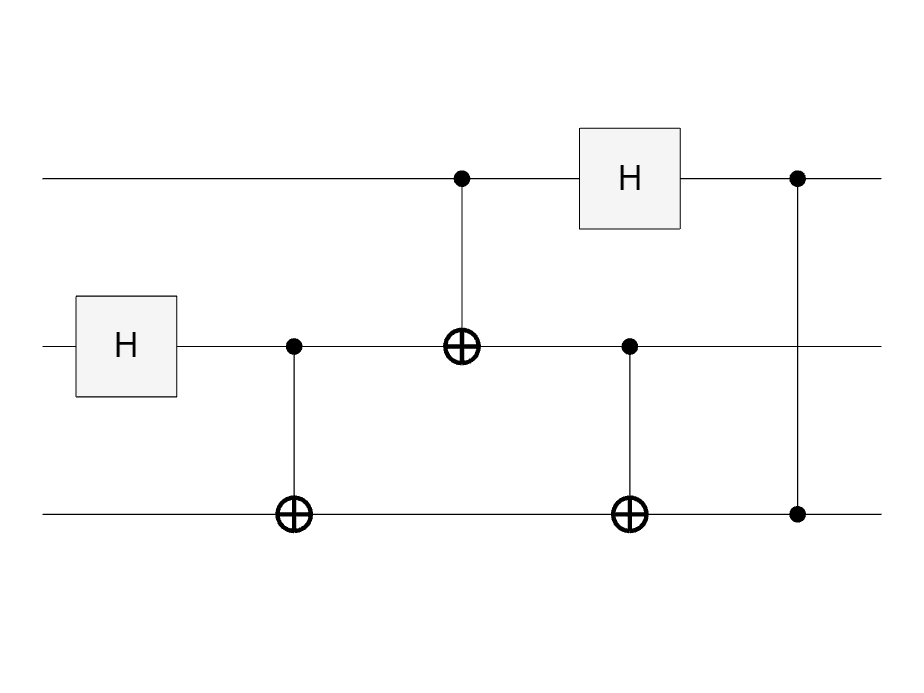

clc; clear; close all;

qc = quantumCircuit(3, Name = "Qubit_Teleportation"); %initializing the three qubits

%Alice holds qubit2
%Bob holds Qubit3
%Qubit1 is with Alice which needs to be teleported to Bob, let's call it Q

% Preparing the Bell state between qubits 2 and 3
QbellState = [hGate(2) cxGate(2,3)];


%Alice performs operations on both the qubits which are with her.
encodedQ = TelPort(QbellState);

%Bob performs operations on his qubit based on the data from Alice
decodedQ = recQubit(encodedQ);


plot(decodedQ);

%initialising the state of the composite system, Q is in the state '+' 
initState = quantum.gate.QuantumState('+00');

Q2Bob = simulate(decodedQ, initState); %teleporting qubit... Q  to Bob

%partial measurement is not possible without QuantumReg and classicalReg,
%continuing without measurement

finalState = formula(Q2Bob)

finalState = "1 * |+++>"


% Extract the part of the string that contains the qubit states
state_part = extractBetween(finalState, "|", ">");

% Display the qubit that is with Bob which is teleported by Alice i.e, Q
telPorted_qubit = state_part{1}(3);
fprintf('The Teleported Qubit is: %s\n', telPorted_qubit);

The Teleported Qubit is: +


%creating the state vector of Bob's qubit to plot on Blochsphere
BobQ = quantum.gate.QuantumState(telPorted_qubit);

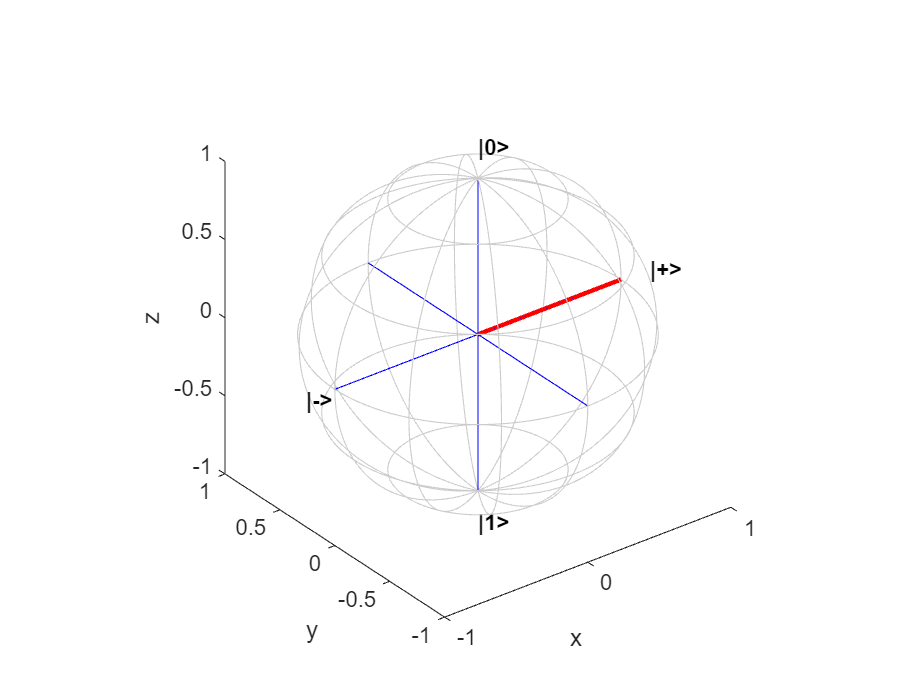

%Alice Actions on Qubit 1 and 2
function encodedQ = TelPort(QbellState)
    gates = [cxGate(1,2) hGate(1)];
    encodedQ = quantumCircuit([QbellState gates]);
end

%Bob Actions on Qubit 3
function decodedQ = recQubit(encodedQ)
% switch encodedQ
%     case "00"
%         gates2 = 1;
%     case "01"
%         gates2 = [xGate(1)];
%     case "10"
%         gates2 = [zGate(1)];
%     case "11"
%         gates2 = [xGate(1) zGate(1)];
%     otherwise
%         gates2 = 1;
% end

encodedQ.Gates = [encodedQ.Gates' cxGate(2,3) czGate(1,3)];
decodedQ = encodedQ;

end


%visualising Bob's state on Bloch sphere
function plotBlochSphere(u)
% Plot Bloch sphere representation from 2-D complex amplitudes

%   Copyright 2021-2023 The MathWorks, Inc.

arguments
    u {mustBeNumeric,mustBeVector}
end

% Compute Bloch sphere representation (3-D real) from a 2-D complex vector
P = mapToBlochSphere(u);

% Grid view of the sphere
alpha = linspace(0,2,101)';
alpha(end+1) = NaN;
beta = linspace(0,1,7);
beta(end) = [];
gamma = linspace(-0.5,0.5,7);

% Meridian lines
meridianCoordinates = cat(3, cospi(beta).*cospi(alpha), ...
    sinpi(beta).*cospi(alpha), repmat(sinpi(alpha), 1, length(beta)));

% Latitude circles
latitudeCoordinates = cat(3, cospi(gamma).*cospi(alpha), ...
    cospi(gamma).*sinpi(alpha), repmat(sinpi(gamma), length(alpha), 1));

xyz = [reshape(meridianCoordinates,[],3); reshape(latitudeCoordinates,[],3)];

% Plot the grid and coordinate system
plot3(xyz(:,1), xyz(:,2), xyz(:,3), "k-", Color=0.8*[1 1 1])
hold on
plot3([1 0 0; -1 0 0], [0 1 0; 0 -1 0], [0 0 1; 0 0 -1], "b")

% Label qubit basis vectors for X basis and Z basis
text([0 0 1.2 -1.2], [0 0 0 0], [1.2 -1.2 0 0], ["|0>" "|1>" "|+>" "|->"], ...
    FontWeight="bold")

% Configure axis view
xlabel("x")
ylabel("y")
zlabel("z")
axis equal

% Plot the vector
plot3([0 P(1)], [0 P(2)], [0 P(3)], "r-", LineWidth=2)
plot3([0 P(1) P(1)], [0 P(2) P(2)], [0 0 P(3)], "r--")

hold off
end


function P = mapToBlochSphere(u)
% Compute Bloch sphere representation (3-D real) from a 2-D complex vector

theta = 2*atan2(abs(u(2)),abs(u(1)));
phi = angle(u(2)*conj(u(1)));
P =  [sin(theta)*cos(phi) sin(theta)*sin(phi) cos(theta)];

end

%Amplitude vector of the teleported qubit
vectAmps = BobQ.Amplitudes;

%visualising teleported qubit on the Bloch Sphere
plotBlochSphere(vectAmps);